% process auto center offline simply

timeOffset = nan;
channel = 'Amplifier_Ch1';
processOptions = struct;

% load('/Users/sam/analysis/cellData/051216Ac4.mat')
% sessionId = 201651215217;

% load('/Users/sam/analysis/cellData/032416Ac9.mat')
% sessionId = 2016324173256;

% load('/Users/sam/analysis/cellData/060216Ac2.mat')
% sessionId = 2016512181624;

% load('/Users/sam/analysis/cellData/033016Bc8.mat')
% sessionId = 201633020044;

% load('/Users/sam/analysis/cellData/010716Ac4.mat') % WC ON
% sessionId = 1;

% load('/Users/sam/analysis/cellData/121616Ac7.mat')
% sessionId = 2016121616210;
% timeOffset = 0.3;

% load('/Users/sam/analysis/cellData/081517Ac3.mat')
% sessionId = {'2017815142854','2017815143647'};
% sessionId = 2017815142854; % on ex
% sessionId = 2017815143647; % off ex
% sessionId = 2017815152043; % on in
% timeOffset = 0.09;
% sessionId = 201781515724; % off in

% load('/Users/sam/analysis/cellData/101917Ac1.mat') % Iclamp on off
% sessionId = '20171019132525';

% load('/Users/sam/analysis/cellData/110917Ac8.mat') % big ex in
% sessionId = 1;

% load('/Users/sam/analysis/cellData/011718Ac1.mat') % HD2 CC
% sessionId = {'201811712578','2018117131112'};

% load('/Users/sam/analysis/cellData/011718Ac4.mat') % UHD use min response mode to toss noise
% sessionId = {'201811716347','20181171609'};


% load('/Users/sam/analysis/cellData/012418Bc3.mat')
% sessionId = {'2018124161454','201812416623'};

% load('/Users/sam/analysis/cellData/013118Ac24.mat')
% sessionId = {'201813117312','201813117151'};
% timeOffset = .39;


% load('/Users/sam/analysis/cellData/012418Bc2.mat')
% sessionId = {'2018124143353','201812414403'};
% sessionId = {'2018124143353'};
% sessionId = {'201812414403'};


% load('/Users/sam/analysis/cellData/021318Ac10.mat')
% % 201821317324 % -60 and 20
% % 201821317473 % -38 and -5
% % 201821318150 % -75 and 35
% % 2018213181637 % -50 and 10
% sessionId = {'201821318150'};
% timeOffset = .05;

% load('/Users/sam/analysis/cellData/021618Ac8.mat') % good Fmon vclamp offset
% sessionId = {'2018216181428'};
% timeOffset = .06;


% load('/Users/sam/analysis/cellData/021618Ac3.mat') % good Fmon vclamp offset
% sessionId = {'2018216144613'};
% timeOffset = .06;


% load('/Users/sam/analysis/cellData/022118Ac1.mat') % HD1 vclamp offset
% sessionId = {'2018221143242'};

% load('/Users/sam/analysis/cellData/022118Ac6.mat') % Fmon vclamp, weak signals though
% sessionId = {'2018221174338'};
% timeOffset = .09;

% load('/Users/sam/analysis/cellData/022118Ac5.mat') % Fmon vclamp, solid ON
% sessionId = {'201822116948'};
% timeOffset = .05;


% load('/Users/sam/analysis/cellData/031518Ac1.mat') % Fmon and Fmoff pair
% sessionId = {'2018315125326'}; % fmon ca
% sessionId = {'2018315131858'}; % fmon  cc
% sessionId = {'2018315144559'}; % fmoff cc % original centering with fmon
% sessionId = {'2018315145729'}; % fmoff cc % centered over dendrites, between fmon and fmoff somas
% sessionId = {'2018315151833'}; % fmoff, fmon pair cc (Bad fmon)
% sessionId = {'2018315131858', '2018315144559'}
% channel = 'Amplifier_Ch1';
% timeOffset = .04;


% load('/Users/sam/analysis/cellData/032318Ac1.mat') % unknown rgc iclamp
% sessionId = {'2018323113246'};
% timeOffset = .07;

% load('/Users/sam/analysis/cellData/032318Ac8.mat') % OODS
% sessionId = {'2018323151341'};
% sessionId = {'2018323151739'};
% sessionId = {'2018323151948'};
% timeOffset = .05;

% load('/Users/sam/analysis/cellData/032318Ac5.mat') % 
% sessionId = {'201832313277'};
% timeOffset = .05;


% load('/Users/sam/analysis/cellData/033018Ac17.mat') % HD2
% sessionId = {'2018330191823'};
% timeOffset = .05;

% load('/Users/sam/analysis/cellData/040618Ac2.mat') % Fmon (ch2) and Fmoff (ch1) pair
% sessionId = {'20184617812'}; % 300 diam, 79 positions
% sessionId = {'201846163153'}; % 370 diam, 62 positions
% sessionId = {'201846161146'}; % 370 diam, 62 positions, noisy data

% load('/Users/sam/analysis/cellData/041118Ac6.mat') % Fmon (ch2) and Fmoff (ch1) pair
% sessionId = {'2018411172816'}; % pre
% timeOffset = .04;
% sessionId = {'2018411184020'};  % no response
% sessionId = {'2018411185454'}; % decent tiny responses, On and Off
% timeOffset = .4;
% sessionId = {'20184111934'}; % response only ON, in recovery from dark spot
% timeOffset = .4;

load('/Users/sam/analysis/cellData/041118Bc7.mat') % Fmon
sessionId = {'2018411141554'};
% sessionId = {'2018411142152'};
% sessionId = {'2018411151851'};
% sessionId = {'201841115253'};

timeOffset = .04;

channel = 'Amplifier_Ch1';


processOptions.temporalBufferSize = [.1, .1];
processOptions.repeatCombinationMode = 'median';
processOptions.temporalUseOffSegment = 0;

% process

epochData = cell(1);
ei = 1;
for i = 1:length(cellData.epochs)
    epoch = cellData.epochs(i);
    if ~isnan(timeOffset)
        epoch.attributes('timeOffset') = timeOffset;
    end
    sid = epoch.get('sessionId');
    if ~isnan(sid)
        fprintf('session found: %s\n',sid);
    end
    protocolVersion = epoch.get('protocolVersion');
    
    matched = 0;
    
    if iscell(sessionId)
        for a = 1:length(sessionId)
            if strcmp(sid, num2str(sessionId{a}))
                matched = 1;
            end
        end
        
    else 
        
        if sid == sessionId | strcmp(sid, num2str(sessionId))
            matched = 1;
        end
    end
    
    if matched
%         if epoch.get('presentationId') > 2
%             continue
%         end
        
        if strcmp(epoch.get('sessionId'), '2018315131858')
            epoch.attributes('ampHoldSignal') = 10;
        elseif strcmp(epoch.get('sessionId'), '2018315144559')
            epoch.attributes('ampHoldSignal') = 20;
        end

        sd = ShapeData(epoch, 'offline', channel);
        epochData{ei, 1} = sd;
        ei = 1 + ei;
%         epoch.attributes('timeOffset')

    end
end

session found: 2018411141554


Starting ShapeData with channel Amplifier_Ch1
Rotating positions by 270 deg


session found: 2018411141554


Starting ShapeData with channel Amplifier_Ch1
Rotating positions by 270 deg


session found: 2018411142152
session found: 2018411151851
session found: 2018411151851
session found: 201841115253
session found: 201841115253






if length(epochData{1}) > 0 %#ok<ISMT>
    % analyze shapedata
    analysisData = processShapeData(epochData, processOptions);
    disp('analysis done');
else
    disp('no epochs found');
    return
end

analysis done


plotShapeData(analysisData, 'printParameters');

num positions: 62
num values: 2
num repeats: 3
holding voltages: 0
holding voltages: 0
             numEpochs: 2
             epochData: {2×1 cell}
        positionOffset: [0 -60]
         spotTotalTime: 0.5000
            spotOnTime: 0.2500
            sampleRate: 1000
             positions: [62×2 double]
          observations: [366×14 double]
    observationColumns: {1×14 cell}
            timeOffset: 0.0400
     validSearchResult: 1
             sampleSet: [200×1 double]

  ShapeData with properties:

                        sessionId: '2018411141554'
                   presentationId: 2
                        epochMode: 'flashingSpots'
                          ampMode: 'Whole cell'
                       ampVoltage: 0
                       sampleRate: 1000
                          preTime: 0.2500
                         stimTime: 1000
                   positionOffset: [0 -60]
                       timeOffset

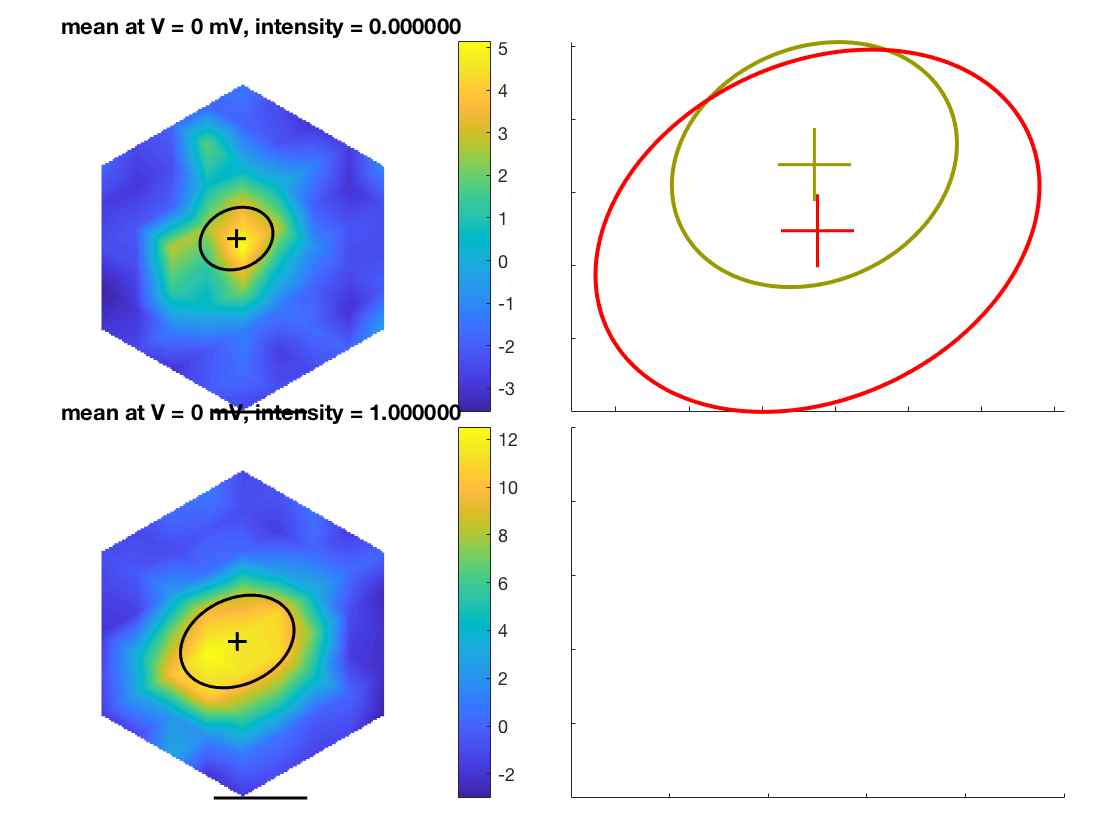

gaussian fit center: -26 um, -12 um
gaussian fit center: -25 um, -30 um


figure(10);clf;
plotShapeData(analysisData, 'plotSpatial_mean');

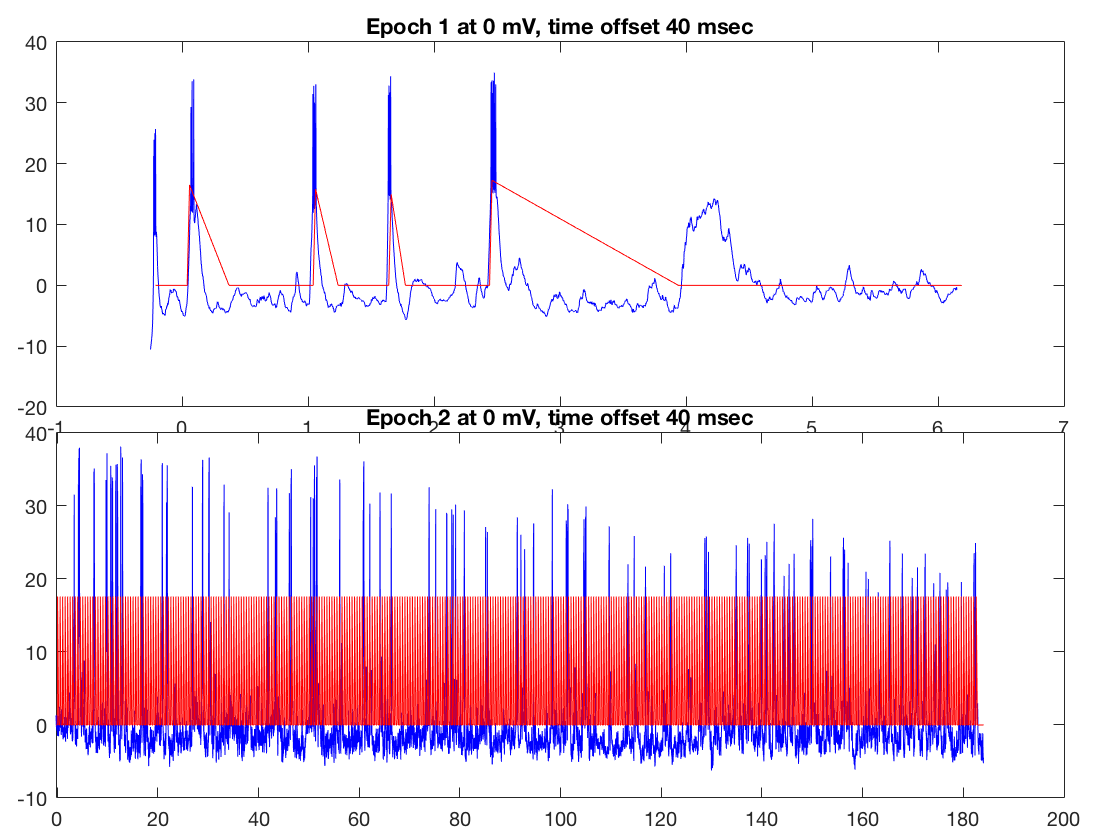


figure(11);clf;
plotShapeData(analysisData, 'temporalResponses');

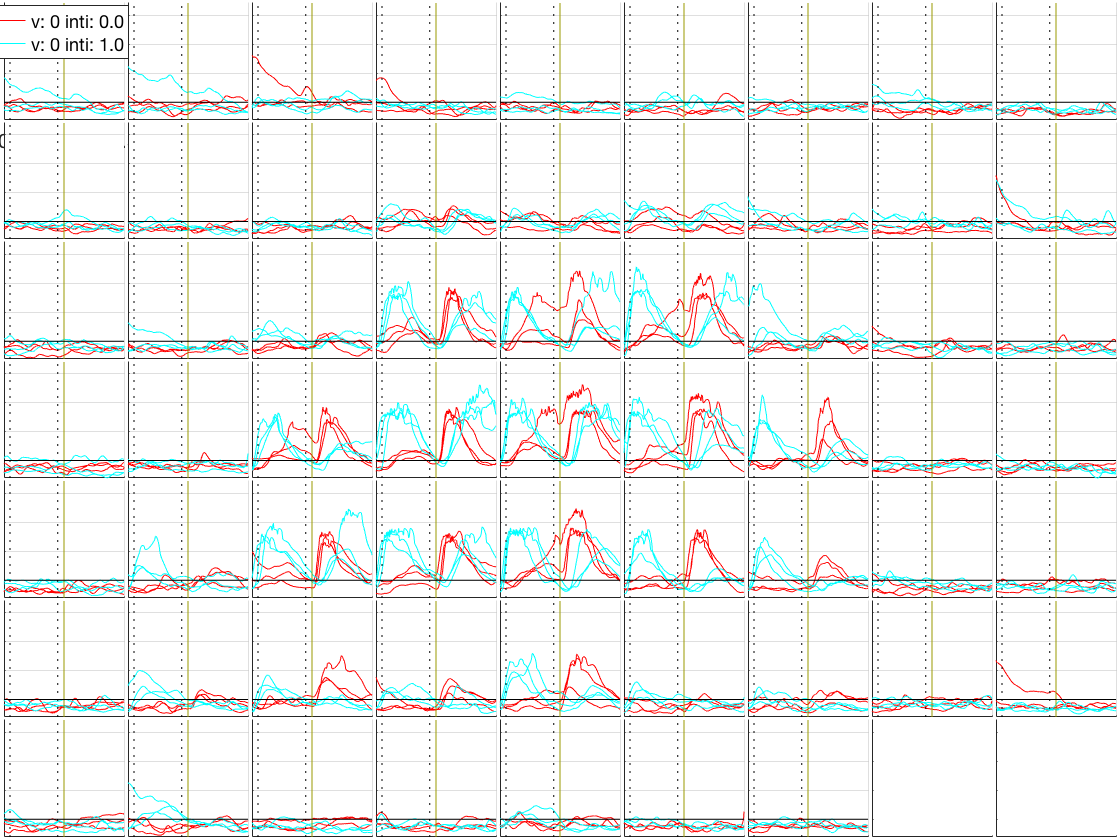

figure(15);clf;
plotShapeData(analysisData, 'responsesByPosition');

gaussian fit center: 8 um, 12 um
gaussian fit center: -8 um, 20 um


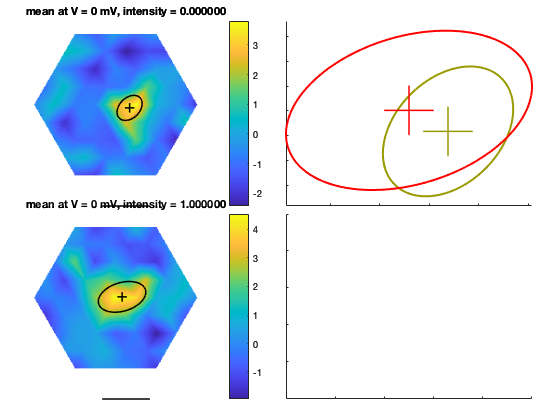


options = struct();

options.displayGaussianFits = 1;
plotShapeData(analysisData, 'plotSpatial_mean', options);

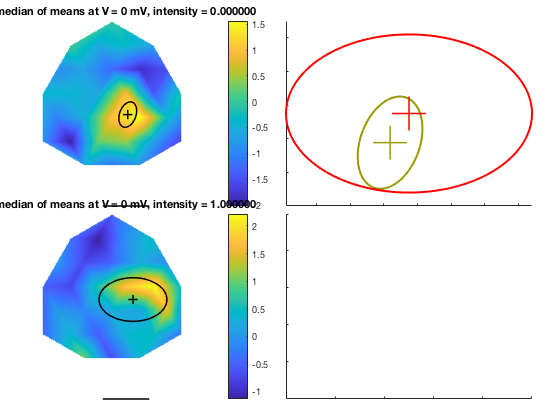

gaussian fit center: 4 um, -2 um
gaussian fit center: 15 um, 15 um


figure(10);clf;
plotShapeData(analysisData, 'plotSpatial_median');

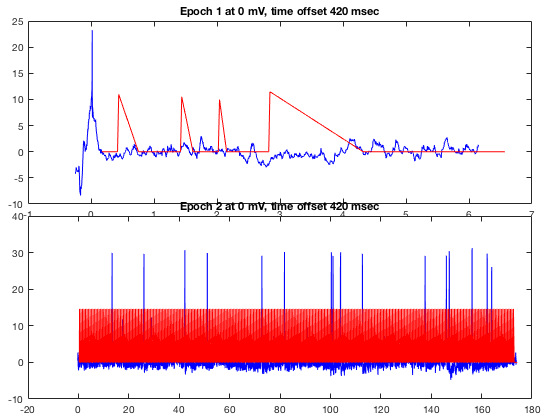

figure(12);clf;

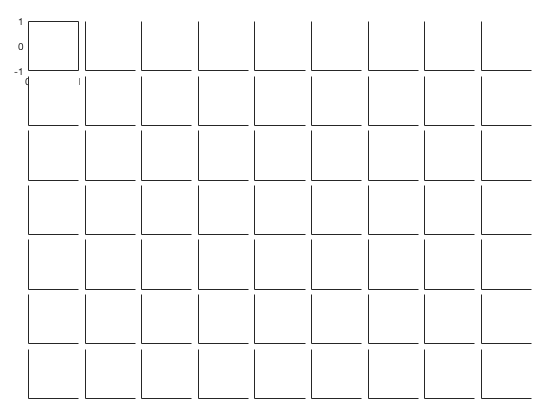

Error using xlim (line 31)
Limits must be a 2-element vector of increasing numeric values.

Error in plotShapeData (line 490)
            xlim(ha(p), [min(voltages),max(voltages)])

plotShapeData(analysisData, 'currentVoltage');

## new plots

figure(13);clf; plotShapeData(analysisData, 'spatialOffset');

Only one voltage in data set


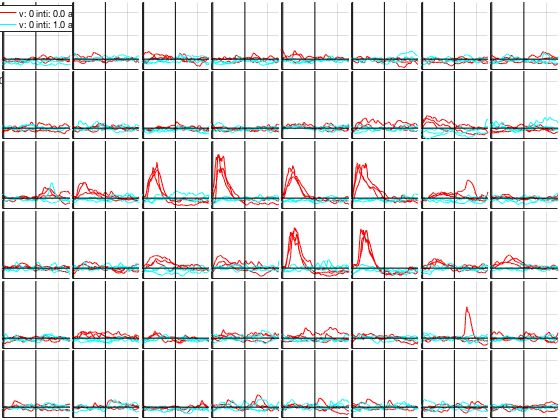

figure(11);clf; plotShapeData(analysisData, 'temporalComponents');

figure(17);clf;
options = struct();
options.overlapThresoldPercentile = 80;
plotShapeData(analysisData, 'overlap', options);


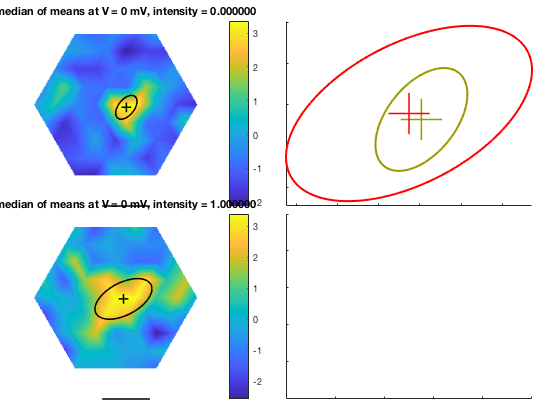

gaussian fit center: 1 um, 13 um
gaussian fit center: -5 um, 16 um


figure(18);clf;
plotShapeData(analysisData, 'plotSpatial_medianOfMeans')

## save maps

% plotShapeData(analysisData, 'plotSpatial_saveMaps');

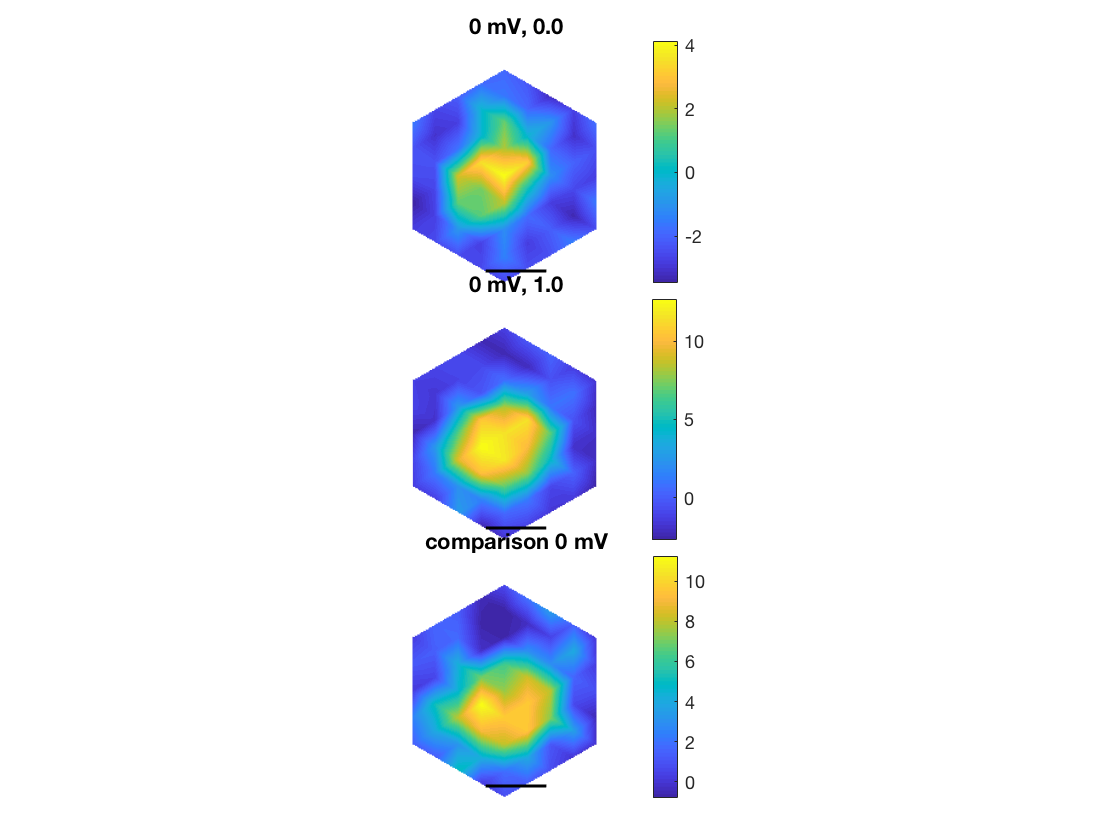

figure(201);clf;
plotShapeData(analysisData, 'wholeCell_comparisons')

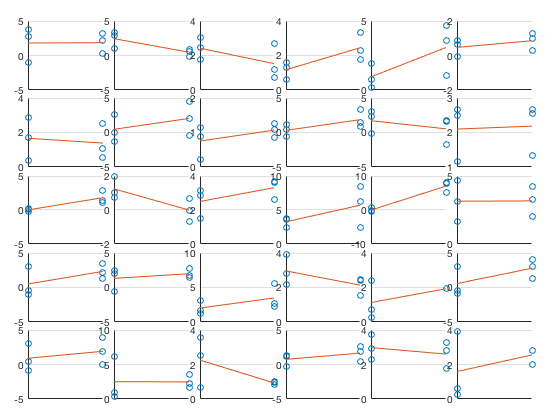

ans = NaN

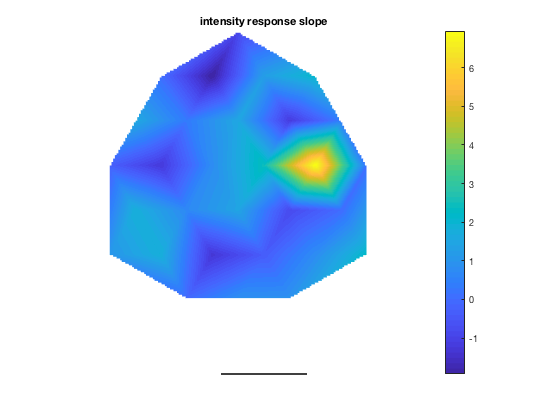


figure(201);clf;
plotShapeData(analysisData, 'subunit')